# House Prices

Date: 5/2017

Data Source: Kaggle.com

## Understand Business Goals 

Objectives:

- Predict house prices

## Prepare and Understand Data

Clean Up

clear
clc
close all


Load Data

data = readtable('train.csv');

predictData = readtable('test.csv');

Statistical summaries

summary(data);


Variables:

    Id: 1460×1 double

        Values:

            Min           1
            Median    730.5
            Max        1460

    MSSubClass: 1460×1 double

        Values:

            Min        20         
            Median     50         
            Max       190         

    MSZoning: 1460×1 cell array of character vectors

    LotFrontage: 1460×1 cell array of character vectors

    LotArea: 1460×1 double

        Values:

            Min             1300
            Median        9478.5
            Max       2.1525e+05

    Street: 1460×1 cell array of character vectors

    Alley: 1460×1 cell array of character vectors

    LotShape: 1460×1 cell array of character vectors

    LandContour: 1460×1 cell array of character vectors

    Utilities: 1460×1 cell array of character vectors

    L

summary(predictData);


Variables:

    Id: 1459×1 double

        Values:

            Min       1461
            Median    2190
            Max       2919

    MSSubClass: 1459×1 double

        Values:

            Min        20         
            Median     50         
            Max       190         

    MSZoning: 1459×1 cell array of character vectors

    LotFrontage: 1459×1 cell array of character vectors

    LotArea: 1459×1 double

        Values:

            Min        1470    
            Median     9399    
            Max       56600    

    Street: 1459×1 cell array of character vectors

    Alley: 1459×1 cell array of character vectors

    LotShape: 1459×1 cell array of character vectors

    LandContour: 1459×1 cell array of character vectors

    Utilities: 1459×1 cell array of character vectors

    LotConf

Feature Engineering (Drop/Create/Convert/Complete)

% Check for missing data
if(nnz(ismissing(data)))
    figure
    imagesc(ismissing(data))
    ax = gca;
    varsTrain = data.Properties.VariableNames;
    ax.XTick = 1:length(varsTrain);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end
% Check for missing predictData data
if(nnz(ismissing(predictData)))
    figure
    imagesc(ismissing(predictData))
    ax = gca;
    varsTest = predictData.Properties.VariableNames;
    ax.XTick = 1:length(varsTest);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end

% Remove
data(:,{'Id'}) = [];
Id = predictData.Id;
predictData(:,{'Id'}) = [];
% Replace
% Convert
vars = data.Properties.VariableNames;
responseVar = 'SalePrice';
predictVars = setdiff(vars,{responseVar});
for k = 1:size(data,2) 
    if iscellstr(data.(vars{k})) 
        data.(vars{k}) = grp2idx(data.(vars{k}));
    end
end
for k = 1:size(predictData,2) 
    if iscellstr(predictData.(predictVars{k})) 
        predictData.(predictVars{k}) = grp2idx(predictData.(predictVars{k}));
    end
end

% Create
% Double check missing data
if ((nnz(ismissing(data))+nnz(ismissing(predictData)))~=0)
    warning('There are missing data. Check!')
end

Exploratory Analysis and Visualizations

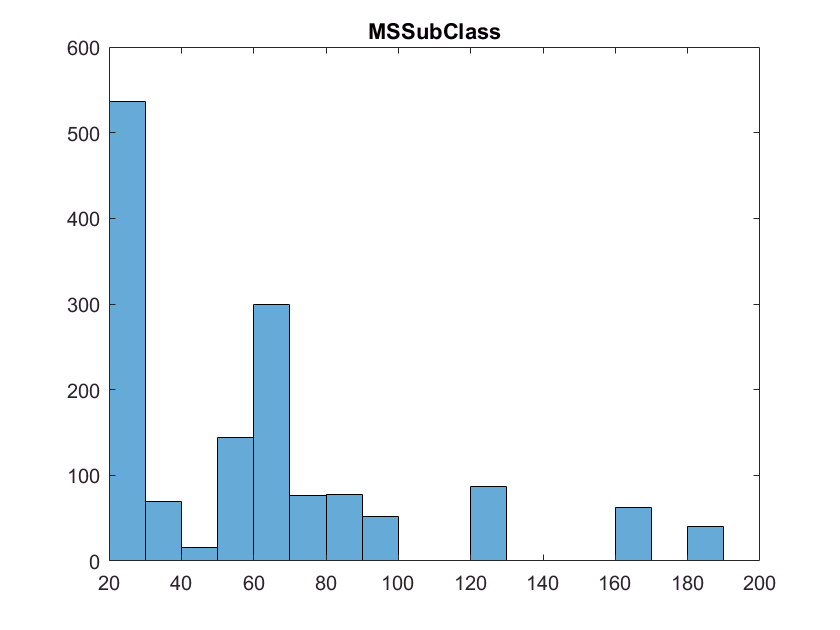

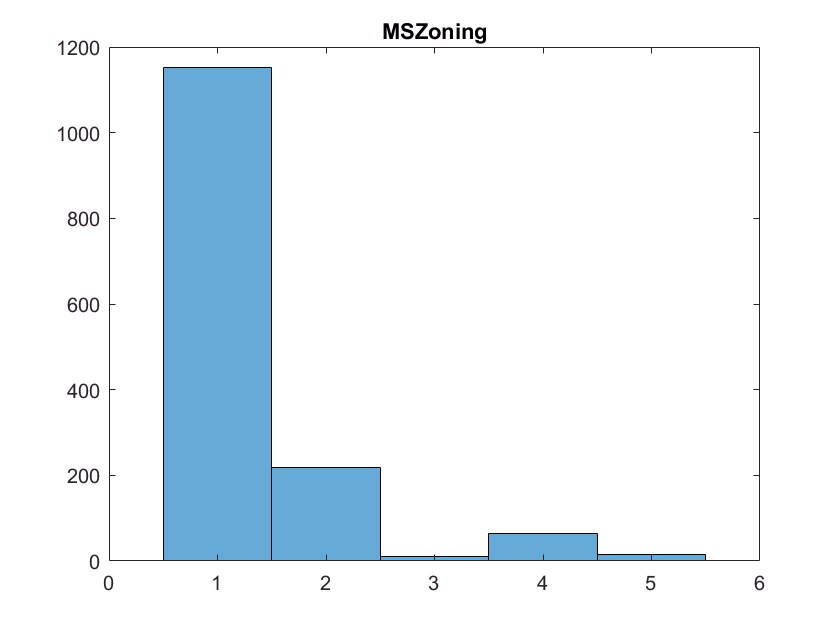

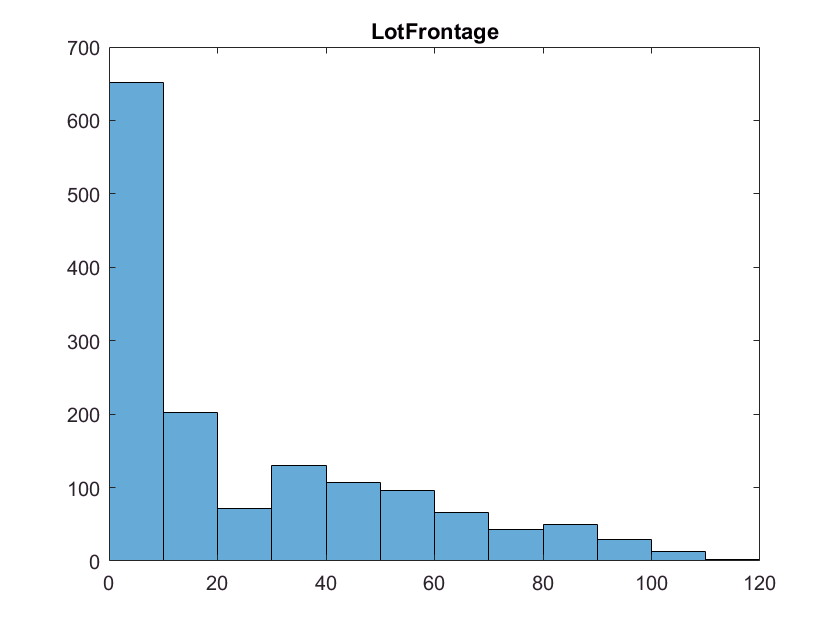

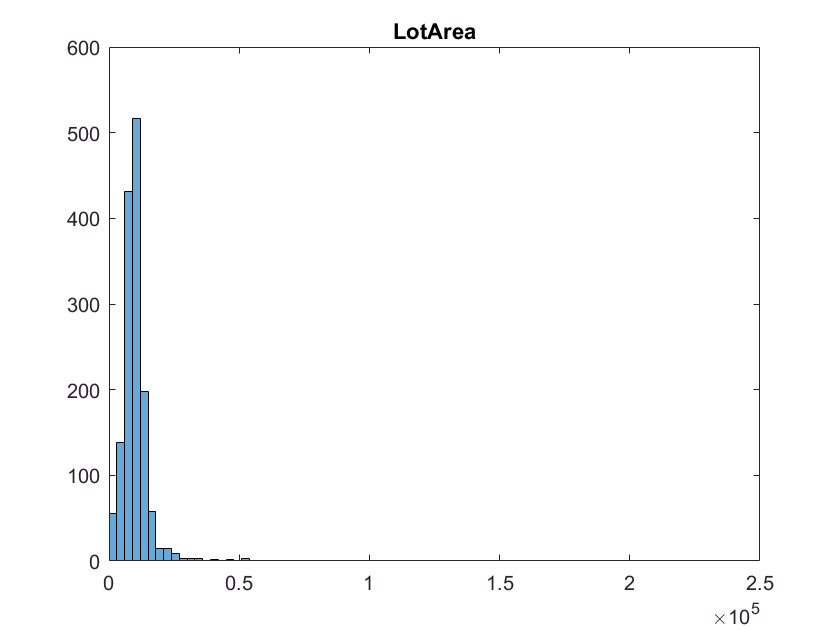

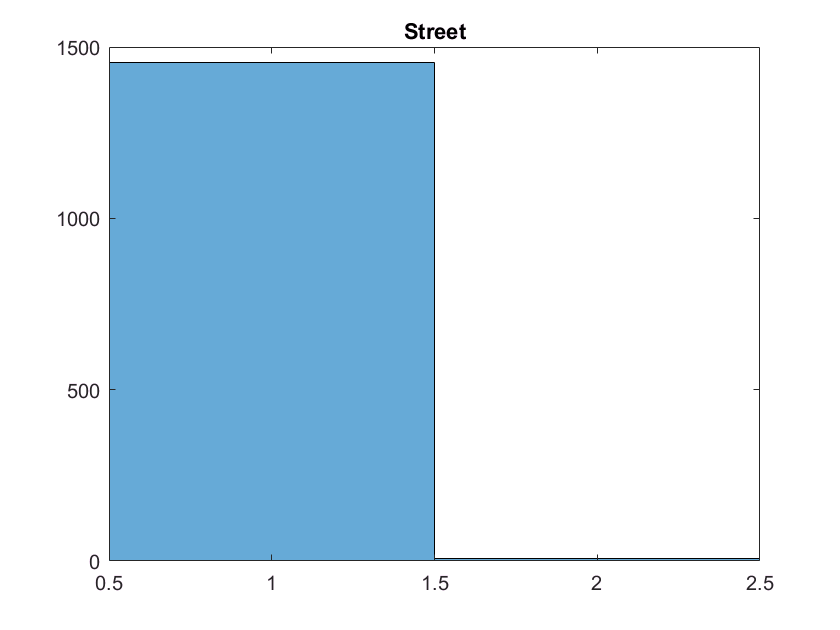

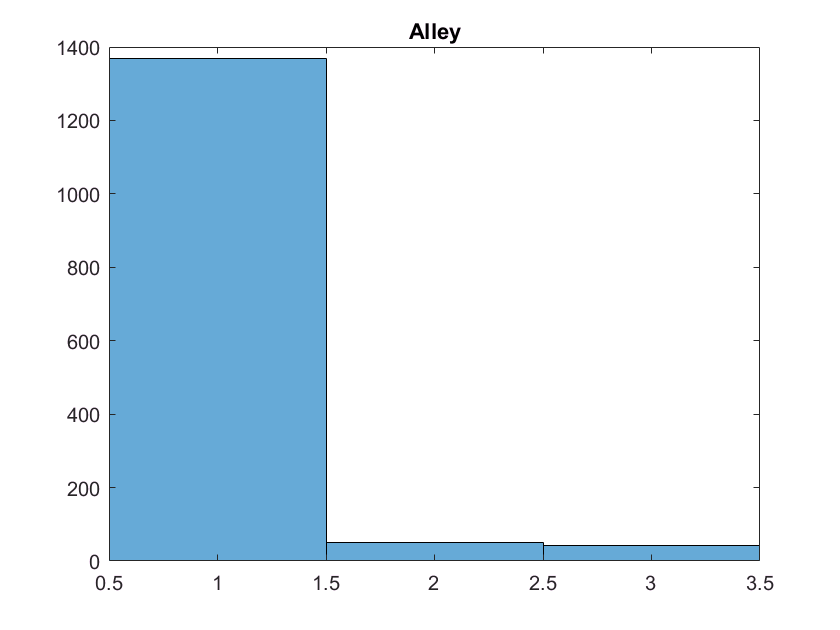

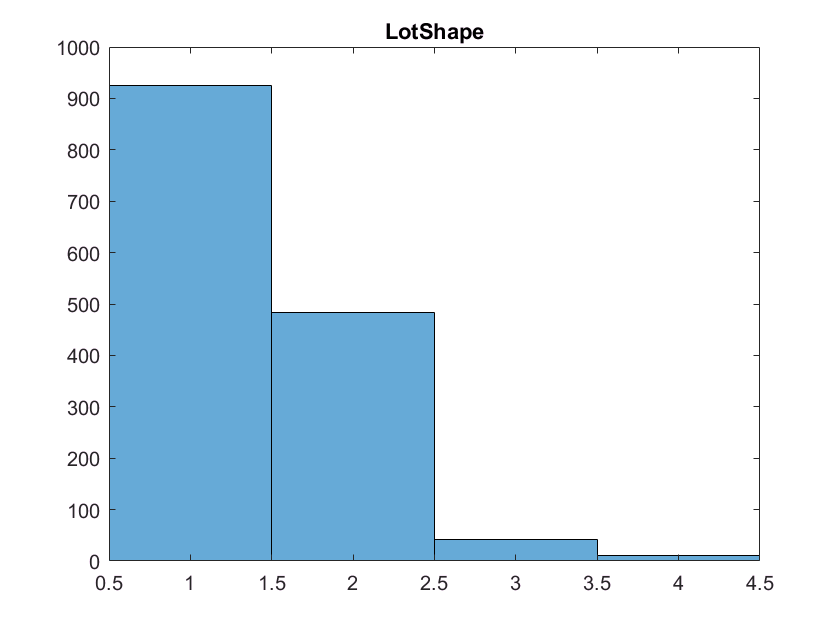

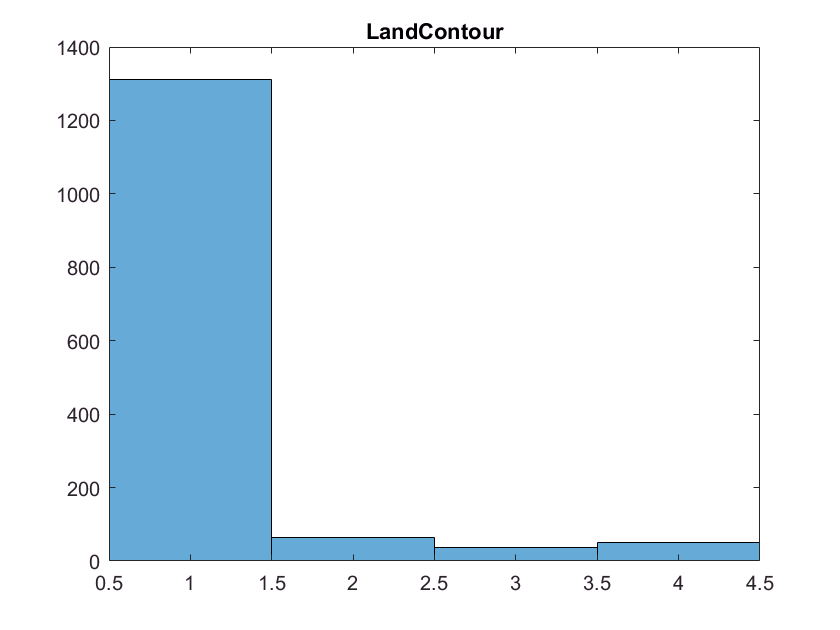

for k = 1:size(data,2) 
    figure
    histogram(data.(vars{k}));
    title(vars{k})
end

Correlation of variables

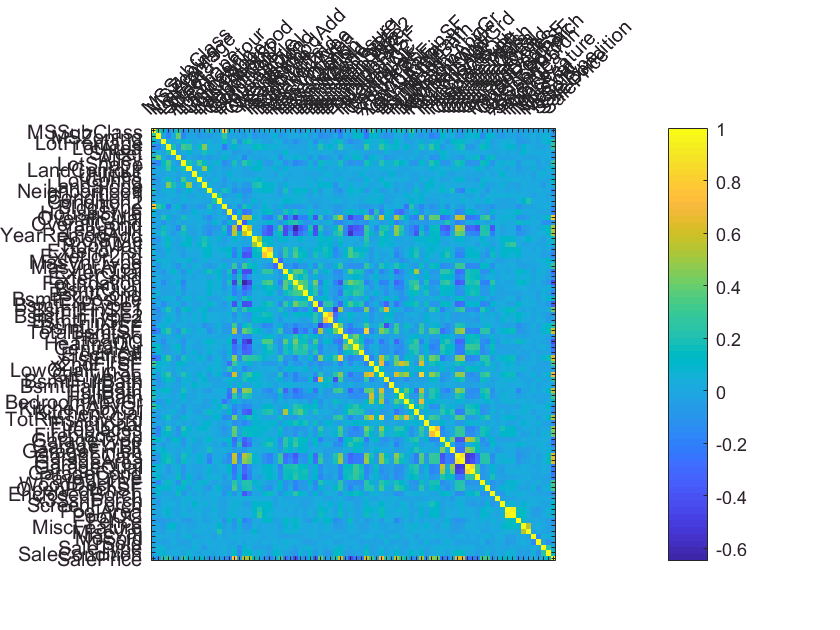

ax =   Axes with properties:

             XLim: [0.5000 80.5000]
             YLim: [0.5000 80.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1802 0.1100 0.4823 0.6872]
            Units: 'normalized'

  Show all properties


figure
imagesc(corr(data{:,:}))
colorbar
ax = gca;
ax.XTick = 1:length(vars);
ax.YTick = 1:length(vars);
ax.XTickLabel = vars;
ax.YTickLabel = vars;
ax.XTickLabelRotation = 45;
ax.XAxisLocation = 'top'

Train and Test Data Preperation

% Use cross validation partition
c = cvpartition(size(data,1),'HoldOut',0.3);
trainData = data(training(c),:);
testData = data(test(c),:);

Predict and Response Variables

PCA preperation

% PCA components and dimension
[pcoeff,pscore,~,~,pexp] = pca(data{:,predictVars});

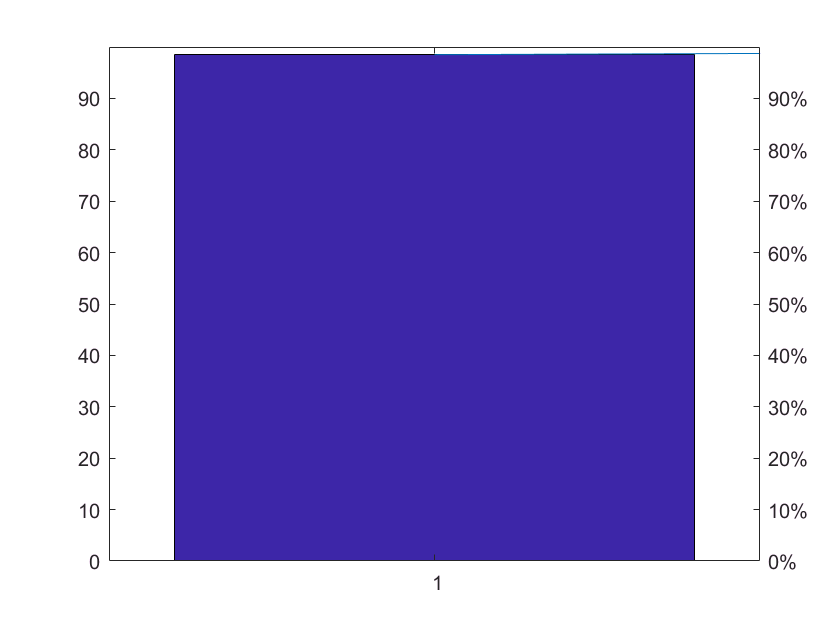

pareto(pexp);

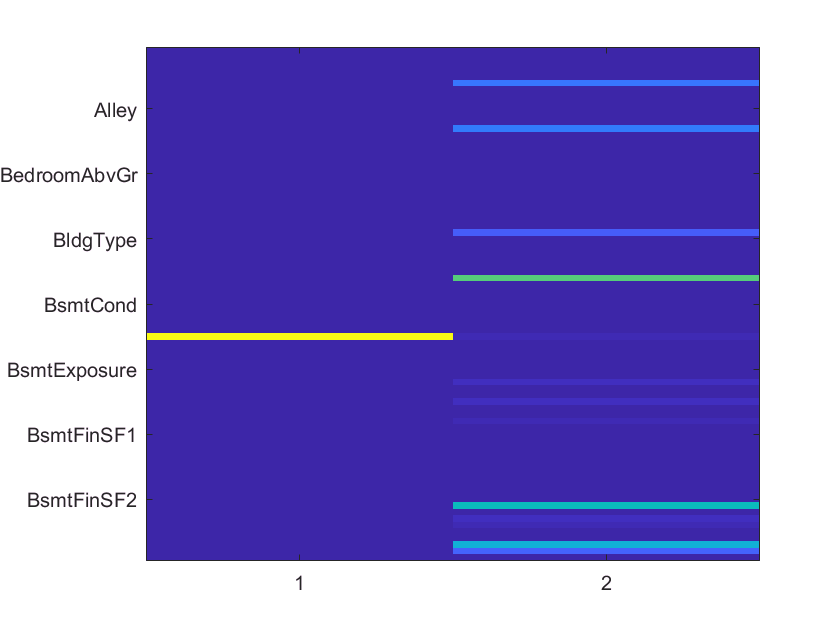

pcaD = 2;
% Show components dependancy
figure
imagesc(abs(pcoeff(:,1:pcaD)));
ax = gca;
ax.XTick = 1:pcaD;
ax.YTickLabel = predictVars;

% PCA train and test data
pcaTrain = pscore(training(c),1:pcaD);
pcaTrainResponse = data{training(c),responseVar};
pcaTest = pscore(test(c),1:pcaD);
pcaTestResponse = data{test(c),responseVar};
% Create prediction data in terms of new components
mu = mean(data{:,predictData.Properties.VariableNames});
pcaPredictData = (predictData{:,:}-mu)*pcoeff(:,1:pcaD); 

Create a structure to store all models

DA = struct;

## Choose Algorithm - Fit, Evaluate and Update Model

Regression

- Multiple Linear Regression

% %%Fit
% mdl = fitlm(data,'linear','ResponseVar',responseVar);
% 
% %%Evaluate
% % Display
% mdl
% % ANOVA
% anova(mdl)
% % Diagnostics Plot
% plotDiagnostics(mdl)
% plotDiagnostics(mdl,'Cookd')
% % Residuals Plot
% plotResiduals(mdl)
% plotResiduals(mdl,'probability')
% plotResiduals(mdl,'fitted')
% % Predictor Effects
% plotSlice(mdl)
% plotEffects(mdl)
% 
% %%Update
% % Remove outliers
% outIdxD = mdl.Diagnostics.CooksDistance>0.25;
% outIdxR = mdl.Residuals.Raw <-1e5 | mdl.Residuals.Raw > 1e5;
% mdl = fitlm(data,'linear','ResponseVar',responseVar,'Exclude',outIdxD & outIdxR)
% 
% DA.LR = mdl;

- Stepwise Linear Regression

- Regularized Linear Regression (Ridge Regression)

% %%Fit
% lambda = 0:0.1:1;
% D = x2fx(data{:,predictVars},'interaction');
% D(:,1) = [];
% mdl = ridge(data{:,responseVar},D,lambda);
% 
% %%Evaluate
% % Display
% figure
% plot(lambda,mdl,'LineWidth',2)
% xlabel('Ridge Parameter')
% ylabel('Standardized Coefficient')
% title('Ridge Trace')
% % Mean Squared Error
% yTest =  predictRidgeResponse(mdl,D,D,data{:,responseVar});
% mse = mean((data{:,responseVar}-yTest).^2);
% figure
% plot(lambda,mse)
% xlabel('Ridge Parameter')
% ylabel('MSE')
% title('Ridge MSE')
% 
% %%Update
% % Choose the lambda with smallest mse
% [~,idx] = min(mse);
% mdl = ridge(data{:,responseVar},D,lambda(idx));
% 
% DA.RidgeR = mdl;

- Regularized Linear Regression (Lasso Regression)

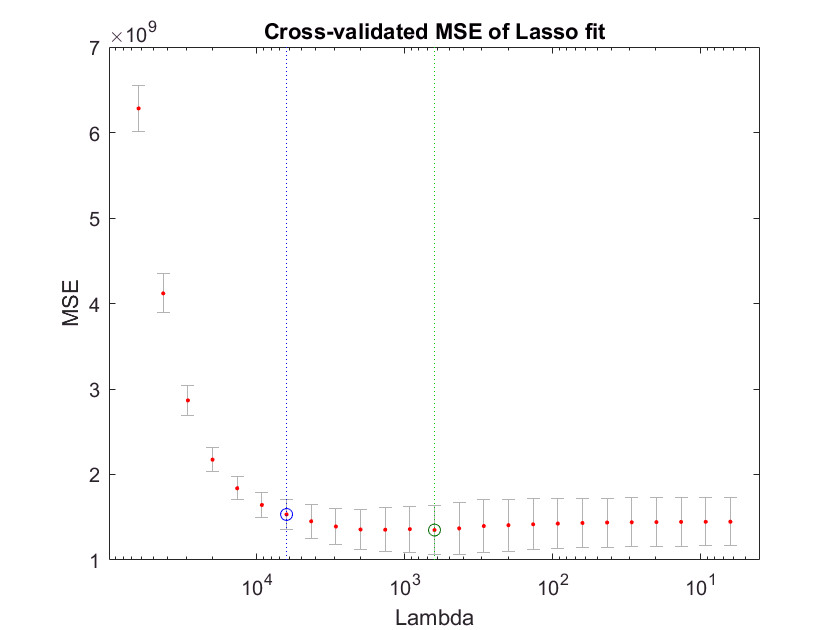

%%Fit
numLambda = 25;
kFold = 5;
[mdl,fitInfo] = lasso(data{:,predictVars},data{:,responseVar},'NumLambda',numLambda,'CV',kFold);

%%Evaluate
% Display
figure
lassoPlot(mdl,fitInfo,'PlotType','CV');

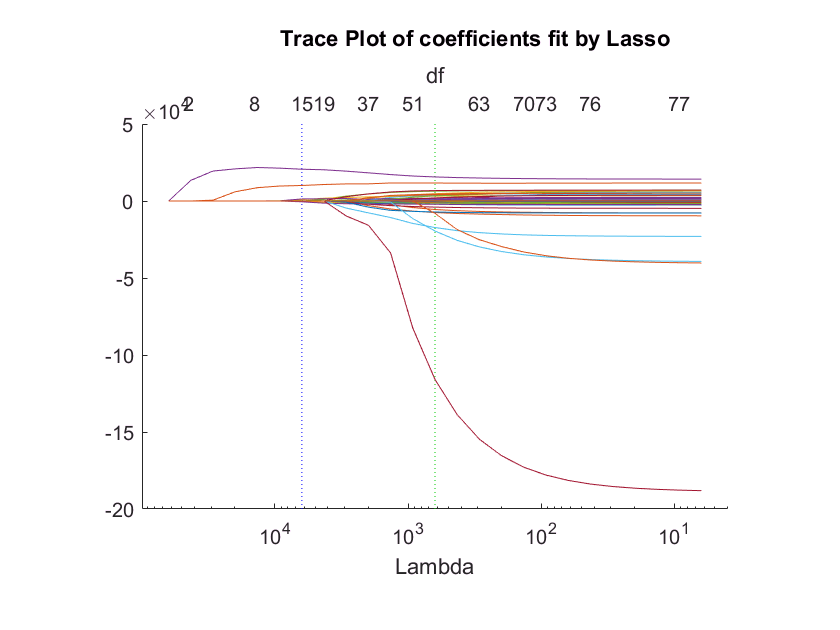

figure
lassoPlot(mdl,fitInfo,'PlotType','Lambda','XScale','log');


%%Update
% Choose the lambda with minimum deviance plus one standard deviation point
idx = fitInfo.Index1SE;
mdl1 = mdl(:,idx);
cnst = fitInfo.Intercept(idx);
mdl2 = [cnst;mdl1];

DA.LassoR = mdl2;

- Generalized Linear Regression (Logistic Regression)

% %%Fit
% mdl = fitglm(data,'interactions','ResponseVar',responseVar,'Distribution','normal')
% 
% %%Evaluate
% % Display
% mdl
% % Diagnostics Plot
% plotDiagnostics(mdl)
% plotDiagnostics(mdl,'Cookd')
% % Residuals Plot
% plotResiduals(mdl)
% plotResiduals(mdl,'probability')
% plotResiduals(mdl,'fitted')
% % Predictor Effects
% plotSlice(mdl)
% 
% %%Update
% % Remove outliers
% outIdxD = mdl.Diagnostics.CooksDistance>0.015;
% mdl = fitglm(data,'interactions','ResponseVar',responseVar,'Exclude',outIdxD)
% 
% DA.GLR = mdl;

- Generalized Linear Regression (Lasso Logistic Regression)

% %%Fit
% numLambda = 25;
% kFold = 5;
% [mdl,fitInfo] = lassoglm(data{:,predictVars},data{:,responseVar},'normal','NumLambda',25,'CV',kFold);
% 
% %%Evaluate
% % Display
% figure
% lassoPlot(mdl,fitInfo,'PlotType','CV');
% figure
% lassoPlot(mdl,fitInfo,'PlotType','Lambda','XScale','log');
% 
% %%Update
% % Choose the lambda with minimum deviance plus one standard deviation point
% idx = fitInfo.Index1SE;
% mdl1 = mdl(:,idx);
% cnst = fitInfo.Intercept(idx);
% mdl2 = [cnst;mdl1];
% 
% DA.LassoGLR = mdl2;

- Regression Tree

% %%Fit
% mdl = fitrtree(trainData,responseVar);
% view(mdl,'mode','graph')
% % Prune the tree
% mdlPrune = prune(mdl,'Level',1);
% view(mdlPrune,'mode','graph')
% DA.rTree = mdl;
% 
% %%Evaluate
% % Model Performence
% err = loss(mdl,testData)
% err = loss(mdlPrune,testData)
% % Cross Validation
% kFold = 5;
% mdlCV = fitrtree(trainData,responseVar,'kFold',kFold);
% errCV = kfoldLoss(mdlCV)
% 
% %%Update
% % PCA
% [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitrtree)
% DA.pcaRTree = mdlPCA;
% % Feature Importance
% figure
% p = predictorImportance(mdl);
% bar(p);
% ax = gca;
% ax.XTickLabel = mdl.PredictorNames;
% ax.XTickLabelRotation = 45;
% toKeep = p>0.5e-3;
% mdlFI = fitrtree(trainData{:,toKeep},trainData{:,responseVar});
% err = loss(mdlFI,testData{:,toKeep},testData{:,responseVar})
% DA.fiRTree = mdlFI;
% % Feature Selection
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitrtree)
% DA.fsRTree = mdlFS;
% % Ensemble Learning
% mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Tree','Type','regression');
% figure
% plot(loss(mdlEL,testData,'mode','cumulative'));
% [err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))
% DA.elRTree = mdlEL;

- SVM Regression 

% %%Fit
% mdl = fitrsvm(trainData,responseVar,'kernelFunction','gaussian','Standardize',1);
% DA.rSVM = mdl;
% 
% %%Evaluate
% % Model Performence
% err = loss(mdl,testData)
% % Cross Validation
% kFold = 5;
% mdlCV = fitrsvm(trainData,responseVar,'kFold',kFold,'KernelFunction','gaussian','Standardize',1);
% errCV = kfoldLoss(mdlCV)
% 
% %%Update
% % PCA
% [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitrsvm)
% DA.pcaRSVM = mdlPCA;
% % Feature Seletion
% [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitrsvm)
% DA.fsRSVM = mdlFS;

- Gaussian Process Regression

Neural Networks

- Self-Organizing Maps

% net = selforgmap([10,10]);
% X = data{:,predictVars}';
% net = train(net,X);
% figure
% plotsomhits(net,X)
% plotsomnd(net,X)
% plotsomplanes(net,X)
% preds = net(predictData{:,:}');

- Feed-Forward Networks

X = data{:,predictVars};
targets = data{:,responseVar};
Xnew = predictData{:,:};
% net = patternnet(3);
net = fitnet([3,2]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
[net,tr] = train(net,X',targets');
preds = net(Xnew');

## Make Predictions

% % Predict classification model
% cMdl = predict(DA.NB,predictData)
% % Predict classification PCA model
% cPCA = predict(DA.pcaNB,pcaPredictData)
% % Predict regression model
% rL = predict(DA.LR,predictData{:,:})
% % Predict ridge regression model
% ridgePredictData = x2fx(predictData{:,:},'interaction');
% ridgePredictData(:,1) = [];
% rRidge = predictRidgeResponse(DA.RidgeR,ridgePredictData,D,data{:,responseVar})
% % Predict generalized lasso regression model
% rLassoGLR = glmval(DA.LassoGLR,predictData{:,:},'logit')
% % Predict Lasso regression
% SalePrice = predictData{:,:}*mdl1;
% submit = table(Id,SalePrice);
% writetable(submit,'submission.csv');
% Predict NN
SalePrice = net(Xnew');
SalePrice = SalePrice';
submit = table(Id,SalePrice);
writetable(submit,'submission.csv');

## **Function Define**

function [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,fitFun)   
    % PCA Function
    
    if(isequal(fitFun,@fitcknn)) 
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'Distribution','normal');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'DiscrimType','linear');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlPCA,pcaTest,pcaTestResponse);
    errCV = kfoldLoss(mdlCV);  
end


function [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,fitFun)
    % Feature Select Function
    
    errorFun = @(Xtrain,ytrain,Xtest,ytest) nnz(ytest ~= predict(fitFun(Xtrain,ytrain),Xtest));
    toKeep = sequentialfs(errorFun,data{:,predictVars},data{:,responseVar},'cv',kFold);
    vars(toKeep)
    if(isequal(fitFun,@fitcknn)) 
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'Distribution','normal');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'DiscrimType','linear');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlFS,testData);
    errCV = kfoldLoss(mdlCV);  
end

function [mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
    % Multiclass Function   
    mdl = fitcecoc(trainData,responseVar,'Learners',template);
    err = loss(mdl,testData)
    mdlCV = fitcecoc(trainData,responseVar,'Learners',template,'kFold',kFold);
    errCV = kfoldLoss(mdlCV) 
end

function yPred =  predictRidgeResponse(mdl,xTest,xTrain,yTrain)
    % Make predictions
    % To make predictions with original data, need to shift coefficients back
    % to unscaled data (RIDGE normalizes data by default)
    m = mean(xTrain);
    s = std(xTrain,0,1)';   
    % (un)Scale b
    bUS = bsxfun(@rdivide,mdl,s);
    % Calculate constant term (from scaling)
    intercept = mean(yTrain)-m*bUS;
    % Make predictions
    yPred = xTest*bUS+intercept;
end
